clc;clear;
%Pre-processing
baby = imread("baby.jpg");
baby_gray = rgb2gray(baby);
baby_gray_double = double(baby_gray);

sobelx = [-1,0,1;
    -2,0,2;
    -1,0,1;];
sobely = [1,2,1;
    0,0,0;
    -1,-2,-1;];
[grad,gradx,grady,grad_deg] = sobelfilter(baby_gray_double,sobelx,sobely);

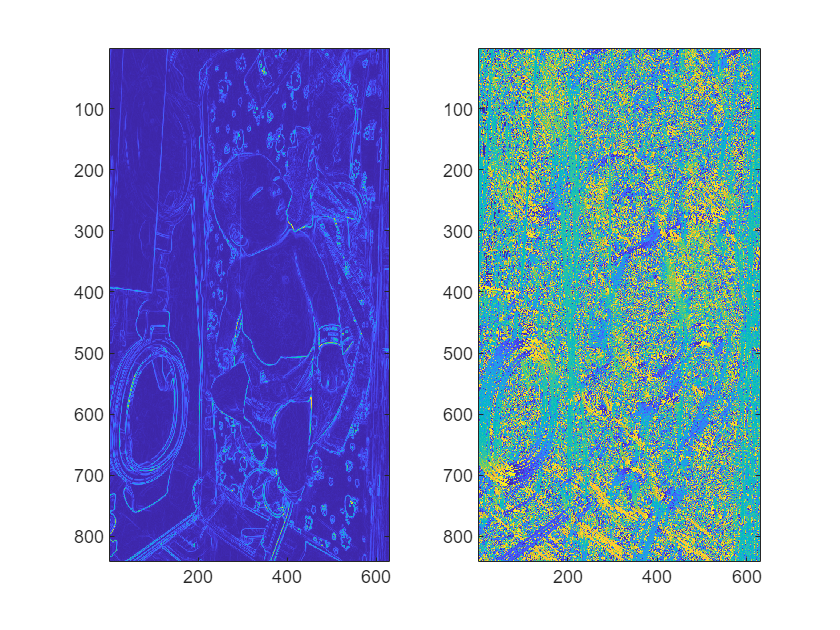

subplot(1,2,1);
imagesc(grad);
subplot(1,2,2);
imagesc(grad_deg);

clc;clear;
%Pre-processing
baby = imread("baby.jpg");
baby_gray = rgb2gray(baby);
baby_gray_double = double(baby_gray);
words = imread("words.jpg");
words = imresize(words,0.25);
words_gray = rgb2gray(words);
words_gray_double = double(words_gray);

%sobel filter
sobelx = [-1,-2,0,2,1;
          -2,-3,0,3,2;
          -3,-5,0,5,3;
          -2,-3,0,3,2;
          -1,-2,0,2,1;];
sobely = [1,2,3,2,1;
          2,3,5,3,2;
          0,0,0,0,0;
          -2,-3,-5,-3,-2;
          -1,-2,-3,-2,-1];
[grad1,gradx1,grady1,grad_deg1,gradx1_square,grady1_square] = sobelfilter(baby_gray_double,sobelx,sobely);
xy1 = gradx1.*grady1;
[grad2,gradx2,grady2,grad_deg2,gradx2_square,grady2_square] = sobelfilter(words_gray_double,sobelx,sobely);
xy2 = gradx2.*grady2;

%gaussian filter
Gaussian_gradx1_square = Gaussian_filter(gradx1_square);
Gaussian_grady1_square = Gaussian_filter(grady1_square);
Gaussian_xy1 = Gaussian_filter(xy1);
Gaussian_gradx2_square = Gaussian_filter(gradx2_square);
Gaussian_grady2_square = Gaussian_filter(grady2_square);
Gaussian_xy2 = Gaussian_filter(xy2);

%Harris Response
R_baby = Harris(Gaussian_gradx1_square,Gaussian_xy1,Gaussian_grady1_square);
R_words = Harris(Gaussian_gradx2_square,Gaussian_xy2,Gaussian_grady2_square);

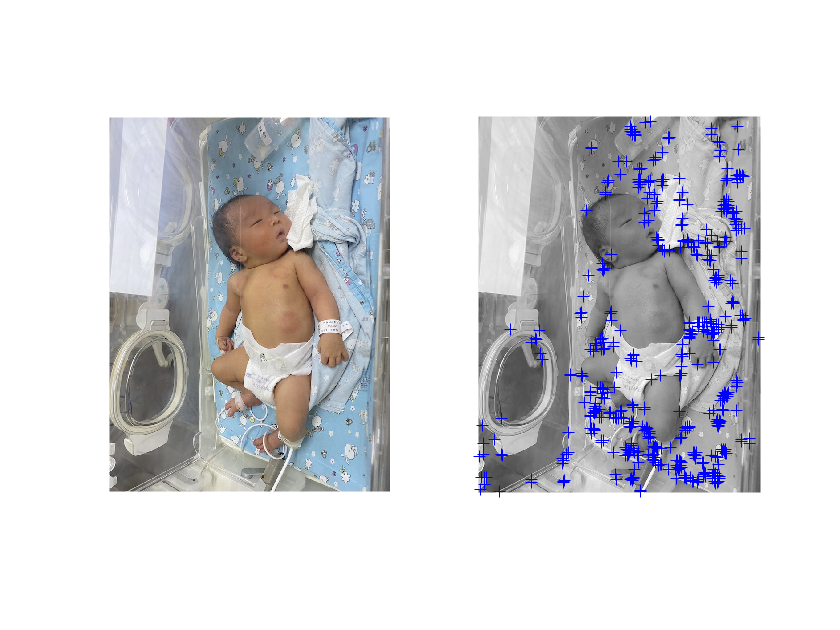

%Thresholding
R_baby_th = max(R_baby(:))*0.01;
R_words_th = max(R_words(:))*0.01;
[max_baby_row,max_baby_col] = Th(R_baby,R_baby_th);
figure
subplot(1,2,1),imshow(baby)
subplot(1,2,2),imshow(baby_gray,[])
hold on
plot(max_baby_col, max_baby_row, 'b+', 'Markersize', 6)
hold off

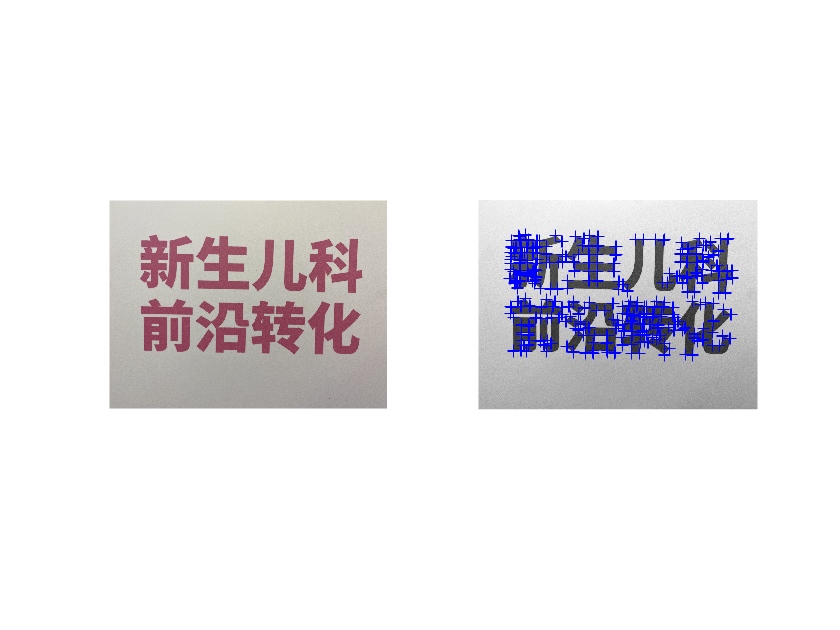


[max_words_row,max_words_col] = Th(R_words,R_words_th);
figure;
subplot(1,2,1),imshow(words)
subplot(1,2,2),imshow(words_gray,[])
hold on
plot(max_words_col,max_words_row, 'b+', 'Markersize', 6)
hold off

function [grad, gradx,grady,grad_deg,gradx_square,grady_square] = sobelfilter(img,sobelx,sobely)
[h,w] = size(img);
sabel_size = size(sobelx,1)-1;
sabel_size_pad = sabel_size/2;
img_pad = padarray(img,[sabel_size_pad,sabel_size_pad],'symmetric');
for i = 1:h
    for j = 1:w
    Gradx = img_pad(i:i+sabel_size,j:j+sabel_size).*sobelx;
    gradx(i,j) = sum(Gradx(:));
    Grady = img_pad(i:i+sabel_size,j:j+sabel_size).*sobely;
    grady(i,j) = sum(Grady(:));
    end
end
gradx_square = gradx.^2;
grady_square = grady.^2;
grad_deg = atand(grady./gradx);     
grad = sqrt(gradx_square + grady_square);
end

function Gaussian_img = Gaussian_filter(img)
sigma = 1.5;  Size = 5;
halfsize = (Size - 1)/2;
gaussion_filter = zeros(Size,Size);

for i = -halfsize:halfsize
    for j = -halfsize:halfsize
    x = j + halfsize + 1;
    y = i + halfsize + 1;
    exponent = exp(-(i^2 + j^2) / (2 * sigma^2));
    gaussion_filter(y, x) = (1 / (2 * pi * sigma^2)) * exponent;
    end
end
gaussion_filter = gaussion_filter / sum(gaussion_filter(:));

paddingSize = floor(Size / 2);
img_padded = padarray(img, [paddingSize paddingSize], 'symmetric');
%conv
filteredImage = zeros(size(img));
for i = 1:size(img, 1)
    for j = 1:size(img, 2)
        window = img_padded(i:i+Size-1, j:j+Size-1);
        value = sum(window(:) .* gaussion_filter(:));
        filteredImage(i, j) = value;
    end
end
Gaussian_img = filteredImage;
end

function R = Harris(B,C,D)
[h,w] = size(B);
R = zeros(h,w);
for i = 1:h
    for j = 1:w
        A = [B(i,j),C(i,j);
            C(i,j),D(i,j)];
        R(i,j) = det(A)-0.04*(trace(A).^2);
    end
end
end

function [point_Row, point_Col] = Th(array,th)
for i = 1:size(array,1)
    for j = 1:size(array,2)
    if array(i,j) < th
        array(i,j) = 0;
    end
    end
end
for i = 1:size(array,1)-2
    for j = 1:size(array,2)-2
        temp_img = array(i:i+2, j:j+2);
        MAX = max(temp_img(:));
        for temp_i = 1:3
            for temp_j = 1:3
                if temp_img(temp_i, temp_j) < MAX
                    temp_img(temp_i, temp_j) = 0;
                end
            end
        end
        array(i:i+2, j:j+2) = temp_img;
    end
end

[point_Row, point_Col] = find(array > 0);



end

